# ECEN5463 | EX 1

Collin Thornton

## Problem 1 

FitzHugh-Nagumo model:

$\dot{\;u} =u-\frac{1}{3}u^3 -w+I$,


$$\dot{\;w\;} =c\left(b_0 +b_1 u-w\;\right)$$


Where $c,b_0 ,b_1 >0$

syms u w I c b0 b1

f = [u-u^3/3-w+I; c*(b0+b1*u-w)];

jac = jacobian(f,[u,w])

$$jac = \left(\begin{array}{cc} 1-u^{2} & -1\\ b_{1}\,c & -c \end{array}\right)$$

### 1-1

Let $c=0\ldotp 1$, $b_0 =2$, and $b_1 =1\ldotp 5$. For each of the values $I=0$ and $I=2$

jac1 = subs(jac, [b1,c], [1.5,0.1]);
f11 = subs(f, [c,b0,b1,I], [0.1,2,1.5,0]);
f12 = subs(f, [c,b0,b1,I], [0.1,2,1.5,2]);

#### 1-1-1 Use linearization to find all equiplibrium points and determine their types

sol = solve(f11==0, 'real', true, 'ReturnConditions', true);
eq_points11 = vpa([sol.u, sol.w],2)

$$eq\_points11 = \left(\begin{array}{cc} -1.5 & -0.32 \end{array}\right)$$

jac11 = cell(size(eq_points11,1),1);
eig11 = cell(size(eq_points11,1),1);

for i = 1:size(eq_points11,1)
    jac11{i} = subs(jac1, u, eq_points11(i,1));
    eig11{i} = eig(jac11{i});
    disp(vpa(eig11{i},2));
end

$$\left(\begin{array}{c} -0.23\\ -1.3 \end{array}\right)$$

sol = solve(f12==0, 'real', true, 'ReturnConditions', true);
eq_points12 = vpa([sol.u, sol.w],2)

$$eq\_points12 = \left(\begin{array}{cc} 0 & 2.0 \end{array}\right)$$

jac12 = cell(size(eq_points12,1),1);
eig12 = cell(size(eq_points12,1),1);

for i = 1:size(eq_points12,1)
    jac12{i} = subs(jac1, u, eq_points12(i,1));
    eig12{i} = eig(jac12{i});
    disp(vpa(eig12{i},2));
end

$$\left(\begin{array}{c} 0.059\\ 0.84 \end{array}\right)$$

**Case **$I=0$: 

$\lambda_1$is purely negative and real, so $x={\left\lbrack -0\ldotp 23,-1\ldotp 3\right\rbrack }^T$ is a stable node

**Case **$I=2$:

$\lambda_1$ is purely positive and real, so $x={\left\lbrack 0,2\right\rbrack }^T$ is an unstable node

#### 1-1-2 Construct the 2D phase portrait on [-4 4] x[-4 4]

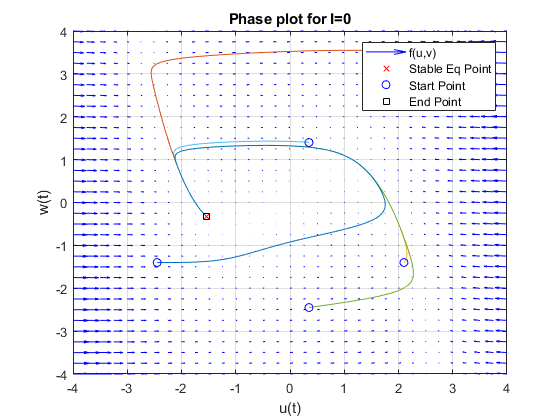

% P = [I;c;b0;b1]
g = @(t,x,P) [x(1)-x(1).^3./3-x(2)+P(1); P(2)*(P(3)+P(4)*x(1)-x(2))];

figure()
params = [0,0.1,2,1.5];
[ut,wt] = meshgrid(-4:0.25:4, -4:0.25:4);

du = zeros(size(ut));
dw = zeros(size(ut));
for i=1:numel(ut)
    fprime = g(0,[ut(i);wt(i)], params);
    du(i) = fprime(1);
    dw(i) = fprime(2);
end
quiver(ut,wt,du,dw, 'b')

grid on
ylim([-4,4])
xlim([-4,4])
xlabel("u(t)")
ylabel("w(t)")
title("Phase plot for I=0")
hold on
plot(eq_points11(1,1),eq_points11(1,2), "rx")


for i = 1:5
    y0 = 0.35*(randi(20,2,1) - 10);
    [ts,ys] = ode45(@(t,y) g(t,y,params),[0,50],[y0]);
    plot(ys(:,1),ys(:,2))
    plot(ys(1,1),ys(1,2),'bo') % starting point
    plot(ys(end,1),ys(end,2),'ks') % ending point
end

legend("f(u,v)", "Stable Eq Point", "", "Start Point", "End Point")

This equilibrium point is behaving as a stable node. There are no oscillatory components in the trajectories, which indicate there is no imaginary component. All trajectories converge, which indicate the real component of each eigen value is negative.

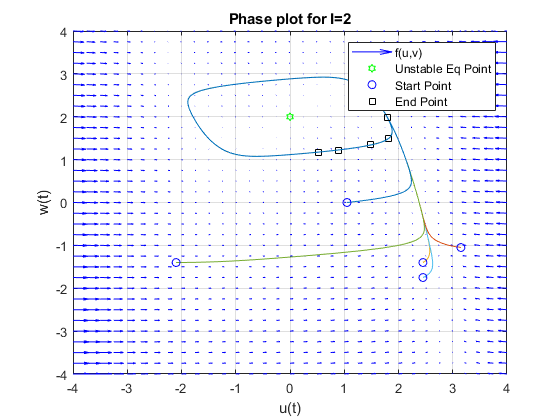

% P = [I;c;b0;b1]
figure()
params = [2,0.1,2,1.5];

du = zeros(size(ut));
dw = zeros(size(ut));
for i=1:numel(ut)
    fprime = g(0,[ut(i);wt(i)],params);
    du(i) = fprime(1);
    dw(i) = fprime(2);
end
quiver(ut,wt,du,dw, 'b')

grid on
ylim([-4,4])
xlim([-4,4])
xlabel("u(t)")
ylabel("w(t)")
title("Phase plot for I=2")
hold on
plot(eq_points12(1,1),eq_points12(1,2), "gh")


for i = 1:5
    y0 = 0.35*(randi(20,2,1) - 10);
    [ts,ys] = ode45(@(t,y) g(t,y,params),[0,50],[y0]);
    plot(ys(:,1),ys(:,2))
    plot(ys(1,1),ys(1,2),'bo') % starting point
    plot(ys(end,1),ys(end,2),'ks') % ending point
end

legend("f(u,v)", "Unstable Eq Point", "", "Start Point", "End Point")

While the linearization shows that there is an unstable node, the phase plot indicates that the equilibrium point behaves more a like a center. The imaginary components are not indicated in the linearization as the oscillations occur too far away from the equilibrium point, which locally behaves like a node. 

#### 1-1-3

The phase plot for case ($I=0$) largely agrees with the linearization analysis, which both show the equilibrium point behaving as a stable node.

There is a disagreement in the second case ($I=2$). While the linearization coorectly predicted the unstability of the equilibrium point, the eigen values had no imaginary components. The phase plot clearly indicates an oscillatory behavior in the trajectory, which makes the equilibrium point appear to be a center. The discrepancy is due to the linearization breaking down as [u,x] moves away from the equiplibrium point.

### 1-2

Let $c=0\ldotp 1$, $b_0 =2$, and $b_1 =0\ldotp 5$. For each of the values $I=0$ and $I=2$

jac2 = subs(jac, [b1,c], [0.5,0.1]);
f21 = subs(f, [c,b0,b1,I], [0.1,2,0.5,0]);
f22 = subs(f, [c,b0,b1,I], [0.1,2,0.5,2]);

#### 1-2-1 Use linearization to find all equiplibrium points and determine their types

sol = solve(f21==0, 'real', true, 'ReturnConditions', true);
eq_points21 = vpa([sol.u, sol.w],2)

$$eq\_points21 = \left(\begin{array}{cc} -2.1 & 0.95 \end{array}\right)$$

jac21 = cell(size(eq_points21,1),1);
eig21 = cell(size(eq_points21,1),1);

for i = 1:size(eq_points21,1)
    jac21{i} = subs(jac2, u, eq_points21(i,1));
    eig21{i} = eig(jac21{i});
    disp(vpa(eig21{i},2));
end

$$\left(\begin{array}{c} -0.12\\ -3.4 \end{array}\right)$$

sol = solve(f22==0, 'real', true, 'ReturnConditions', true);
eq_points22 = vpa([sol.u, sol.w],2)

$$eq\_points22 = \left(\begin{array}{cc} 0 & 2.0\\ -1.2 & 1.4\\ 1.2 & 2.6 \end{array}\right)$$

jac22 = cell(size(eq_points22,1),1);
eig22 = cell(size(eq_points22,1),1);

for i = 1:size(eq_points22,1)
    jac22{i} = subs(jac2, u, eq_points22(i,1));
    eig22{i} = eig(jac22{i});
    disp(vpa(eig22{i},2));
end

$$\left(\begin{array}{c} -0.052\\ 0.95 \end{array}\right)$$

$$\left(\begin{array}{c} -0.3+0.1\,\mathrm{i}\\ -0.3-0.1\,\mathrm{i} \end{array}\right)$$

$$\left(\begin{array}{c} -0.3+0.1\,\mathrm{i}\\ -0.3-0.1\,\mathrm{i} \end{array}\right)$$

**Case **$I=0$: 

$\lambda_1$is purely negative and real, so $x={\left\lbrack -0\ldotp 12,-3\ldotp 4\right\rbrack }^T$ is a stable node

**Case **$I=2$:

$\lambda_1$ is purely real with both positive and negaitve components, so $x={\left\lbrack 0,2\right\rbrack }^T$ is a saddle point

$\lambda_2$ is complex with negaitve real components, so $x={\left\lbrack -1\ldotp 2,1\ldotp 4\right\rbrack }^T$ is a stable spiral

$\lambda_3$ is complex with negative real components, so $x={\left\lbrack 1\ldotp 2,\;2\ldotp 6\right\rbrack }^T$ is a stable spriral

#### 1-2-2 Construct the 2D phase portrait on [-4 4] x[-4 4]

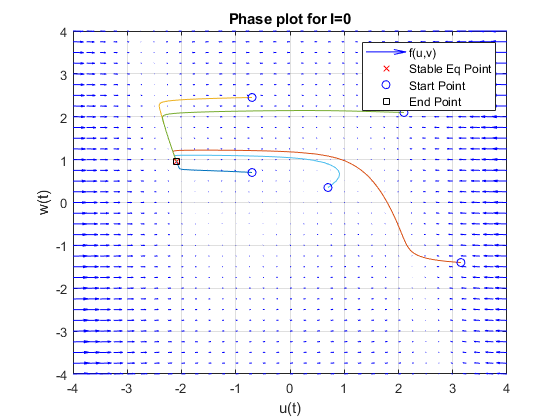

% P = [I;c;b0;b1]
g = @(t,x,P) [x(1)-x(1).^3./3-x(2)+P(1); P(2)*(P(3)+P(4)*x(1)-x(2))];

figure()
params = [0,0.1,2,0.5];

du = zeros(size(ut));
dw = zeros(size(ut));
for i=1:numel(ut)
    fprime = g(0,[ut(i);wt(i)], params);
    du(i) = fprime(1);
    dw(i) = fprime(2);
end
quiver(ut,wt,du,dw, 'b')

grid on
ylim([-4,4])
xlim([-4,4])
xlabel("u(t)")
ylabel("w(t)")
title("Phase plot for I=0")
hold on
plot(eq_points21(1,1),eq_points21(1,2), "rx")


for i = 1:5
    y0 = 0.35*(randi(20,2,1) - 10);
    [ts,ys] = ode45(@(t,y) g(t,y,params),[0,50],[y0]);
    plot(ys(:,1),ys(:,2))
    plot(ys(1,1),ys(1,2),'bo') % starting point
    plot(ys(end,1),ys(end,2),'ks') % ending point
end

legend("f(u,v)", "Stable Eq Point", "", "Start Point", "End Point")

This equilibrium point is behaving as a stable node. There are no oscillatory components in the trajectories, which indicate there is no imaginary component. All trajectories converge, which indicate the real component of each eigen value is negative.

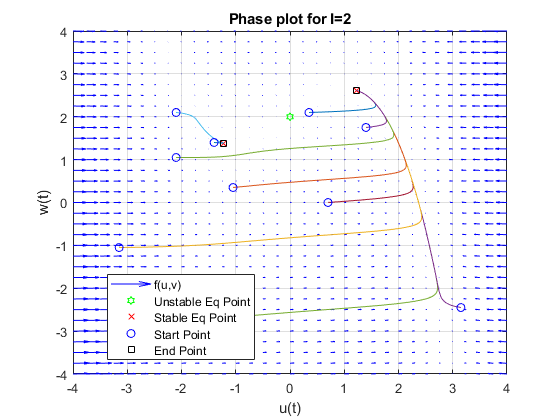

% P = [I;c;b0;b1]
figure()
params = [2,0.1,2,0.5];

du = zeros(size(ut));
dw = zeros(size(ut));
for i=1:numel(ut)
    fprime = g(0,[ut(i);wt(i)],params);
    du(i) = fprime(1);
    dw(i) = fprime(2);
end
quiver(ut,wt,du,dw, 'b')

grid on
ylim([-4,4])
xlim([-4,4])
xlabel("u(t)")
ylabel("w(t)")
title("Phase plot for I=2")
hold on

plot(eq_points22(1,1),eq_points22(1,2), "gh")
plot(eq_points22(2,1),eq_points22(2,2), "rx")
plot(eq_points22(3,1),eq_points22(3,2), "rx")

for i = 1:10
    y0 = 0.35*(randi(20,2,1) - 10);
    [ts,ys] = ode45(@(t,y) g(t,y,params),[0,50],[y0]);
    plot(ys(:,1),ys(:,2))
    plot(ys(1,1),ys(1,2),'bo') % starting point
    plot(ys(end,1),ys(end,2),'ks') % ending point
end

legend("f(u,v)", "Unstable Eq Point", "Stable Eq Point","","", "Start Point", "End Point", "Location", "best")

The phase plot show three equilibrium points: one saddle point and to stable points. The stable points do not exhibit much oscillation, appearing more similiar to stable nodes than stable spirals.

#### 1-2-3

The phase plot for case ($I=0$) largely agrees with the linearization analysis, which both show the equilibrium point behaving as a stable node.

The phase plot for case ($I=2$) largely agrees with the linearization analysis, though the stable equilibrium points do not exhibit much oscillation. This indicates there is little to no imaginary component as [u,v] distances from the point. This being said, the linearization showed a weak imaginary component, suggesting that there wouldn't be much oscillation.

## Problem 2

Consider the system

$f\left(x\right)=\dot{x} =\left\lbrack \begin{array}{c}
-{\textrm{ax}}_1 +x_2 \\
\frac{x_1^2 }{1+x_1^2 }-{\textrm{bx}}_2 
\end{array}\right\rbrack$, where $x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$ and $a,b>0$

### 2-1 Show that the nonnegative quadrant is positively invariant for all $a,b>0$

Positive quadrant: $Q=\left\{x= [x_1,x_2]^T\in\mathbb{R}^2|x_1 \geq0, x_2 \geq 0\right\}$

Positive invariance: $f^T \left(x\right)n\left(x\right)\le 0$, where $n\left(x\right)$is the normal to the boundary at x

2 boundaries to the nonnegative quadrant: ${\partial M}_1 \left(x_1 \right)={\left\lbrack x_1 ,0\right\rbrack }^T$ and $\partial M_2 ={\left\lbrack 0,x_2 \right\rbrack }^T$.

Normals: $n_1 \left(x_1 \right)={\left\lbrack x_1 ,-1\right\rbrack }^T$ and $n_2 \left(x_2 \right)={\left\lbrack -1,x_2 \right\rbrack }^T$

syms x1 x2 a b

f = [-a*x1 + x2; x1^2/(1+x1^2)-b*x2]

$$f = \left(\begin{array}{c} x_{2}-a\,x_{1}\\ \frac{{x_{1}}^{2}}{{x_{1}}^{2}+1}-b\,x_{2} \end{array}\right)$$

n1 = [x1;-1];
n2 = [-1;x2];

f1n = transpose(f)*n1

$$f1n = b\,x_{2}-\frac{{x_{1}}^{2}}{{x_{1}}^{2}+1}+x_{1}\,\left(x_{2}-a\,x_{1}\right)$$

Evaluate the normal at $\partial \;M_1 ={\left\lbrack x_1 ,0\right\rbrack }^T$

f1n = simplify(subs(f1n, x2, 0))

$$f1n = -a\,{x_{1}}^{2}-\frac{{x_{1}}^{2}}{{x_{1}}^{2}+1}$$

solve(f1n, a)

$$ans = -\frac{1}{{x_{1}}^{2}+1}$$

Assuming $a>0$, then $f^T \left(x\right)n_1 \left(x\right)\le 0,x\in \partial \;M_1$

f2n = transpose(f)*n2

$$f2n = a\,x_{1}-x_{2}-x_{2}\,\left(b\,x_{2}-\frac{{x_{1}}^{2}}{{x_{1}}^{2}+1}\right)$$

Evaluate the normal at $\partial \;M_2 ={\left\lbrack 0,x_2 \right\rbrack }^T$

f2n = simplify(subs(f2n,x1,0))

$$f2n = -b\,{x_{2}}^{2}-x_{2}$$

solve(f2n, b)

$$ans = -\frac{1}{x_{2}}$$

Assuming $b>0$, then $f^T \left(x\right)n_2 \left(x\right)\le 0,x\in \partial \;M_2$

Once $x$ enters the nonnegative quadrant ($x\in Q$) and $a,b>0$, then $f\left(x\right)=\dot{x}$ remains positive on the boundaries of the quadrant. This implies that the system will never leave $Q$, thus suggesting that the nonnegative quadrant is positively invariant with respect to $f\left(x\right)$.

### 2-2 Find a condition on the parameters $a$ and $b$ such that the nonnegative quadrant contains multiple equilibria

sol = solve(f==0, [x1,x2]);
eq_points = simplify([sol.x1, sol.x2])

$$eq\_points = \begin{array}{l} \left(\begin{array}{cc} 0 & 0\\ -\frac{\sigma_{1}-1}{2\,a\,b} & -\frac{\sigma_{1}-1}{2\,b}\\ \frac{\sigma_{1}+1}{2\,a\,b} & \frac{\sigma_{1}+1}{2\,b} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{1-4\,a^{2}\,b^{2}} \end{array}$$

The origin is always an equilibrium point

**Condition****:** One other exists if $a^2 b^2 =\frac{1}{4}$

**Condition****: **Two others exist if $a^2 b^2 <\frac{1}{4}$

Determine their type while setting $a=\sqrt{\;\frac{0\ldotp 9}{4b^2 }}$:

f2 = subs(f, a, sqrt(0.9/(4*b^2)));
sol = solve(f2==0, [x1,x2]);
eq_points = simplify([sol.x1, sol.x2])

$$eq\_points = \left(\begin{array}{cc} 0 & 0\\ \frac{\sqrt{10}-1}{3\,b\,\sqrt{\frac{1}{b^{2}}}} & -\frac{\sqrt{10}-10}{20\,b}\\ \frac{\sqrt{10}+1}{3\,b\,\sqrt{\frac{1}{b^{2}}}} & \frac{\sqrt{10}+10}{20\,b} \end{array}\right)$$

jac = jacobian(f2, [x1,x2]);
jacs = cell(size(eq_points,1), 1);
eigs = cell(size(eq_points,1), 1);


Plot eigen values over b and show $\lim_{b-\infty \;} \lambda \left(b\right)$. Note that as $b\to \infty \;$, $a\to 0$, so this condition will never be fully met as $a$ must be greater than 0. 

$$\left(\begin{array}{c} -\infty \\ 0 \end{array}\right)$$

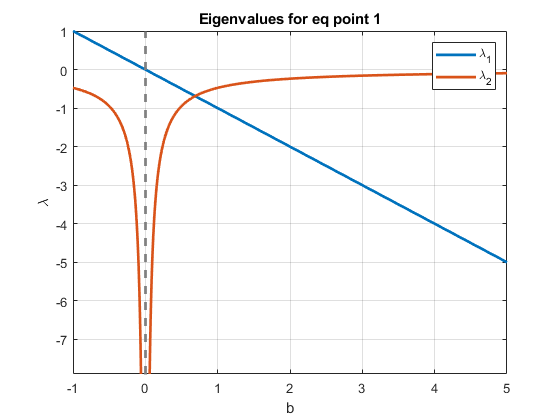

$$\left(\begin{array}{c} -\infty \\ 0 \end{array}\right)$$

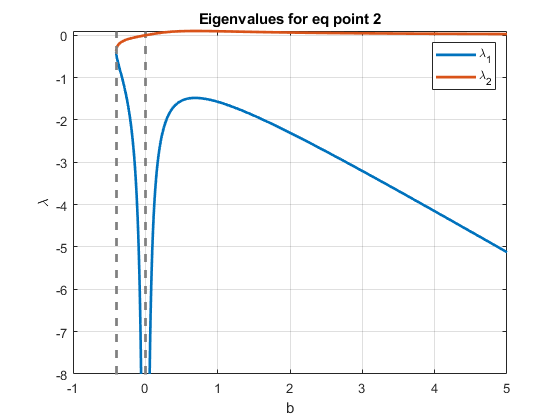

$$\left(\begin{array}{c} -\infty \\ -\infty \end{array}\right)$$

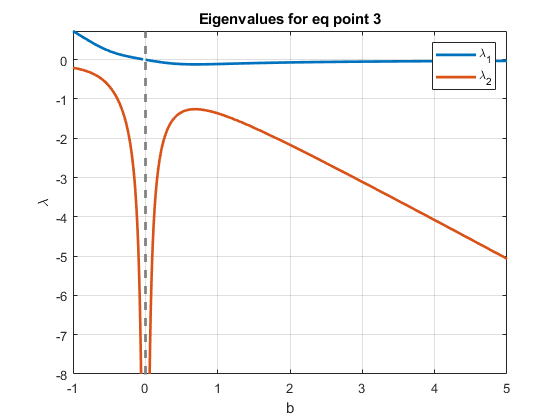

for i = 1:size(eq_points,1)
    jacs{i} = subs(jac, [x1,x2], [eq_points(i,1), eq_points(i,2)]);
    eigs{i} = vpa(eig(jacs{i}),2);
    disp(limit(eigs{i},b,Inf))
    figure()
    fplot(eigs{i}, [-1,5], "LineWidth", 2);
    grid on
    title("Eigenvalues for eq point " + i)
    legend("\lambda_1", "\lambda_2")
    xlabel("b")
    ylabel("\lambda")
end

Thus

$\lambda_1$ is a stable node

$\lambda_2$ is a saddle point

$\lambda_3$ is a stable node